# Experiment with Simple Convolutions

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

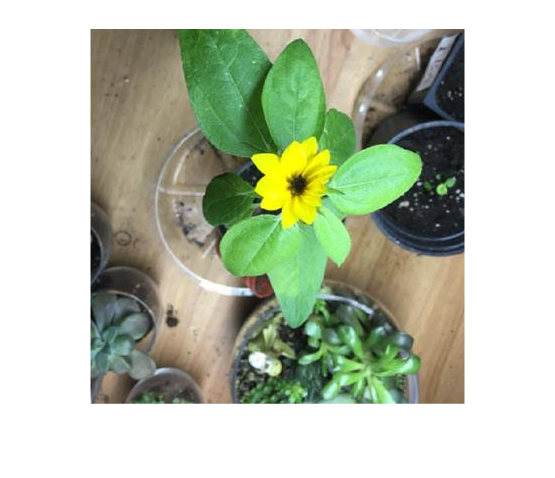

sunIm = imread("../data/sunflower.jpg");
imshow(sunIm)

## Task 1

An RGB image has three channels. To perform convolutions, you need a two-dimensional matrix. You can extract all rows and columns of one of the channels using the colon (`:`) operator:

`image``(``:,:,``n``)`

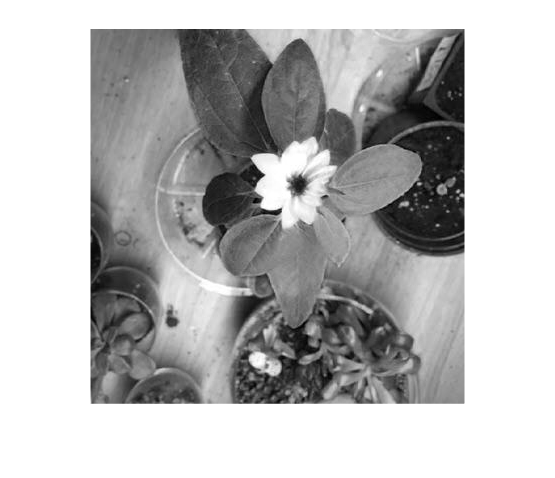

redIm = sunIm(:, :, 1);
imshow(redIm)

## Task 2

You will be using a 3-by-3 matrix called a *kernel* to filter your image. One of the simplest kernels is the *identity* kernel.


$$\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$$


At every pixel, a convolution using the identity kernel will return the same pixel. The resulting image is therefore the same as the original.

identityK = [0 0 0; 0 1 0; 0 0 0]

identityK =      0     0     0
     0     1     0
     0     0     0


## Task 3

You can use your kernel with the `conv2` function to apply a filter to an image.

`filteredim` `=` `conv2``(``kernel``, ``im``)`

identityConv = conv2(identityK, redIm);

## Task 4

It is often useful to use a second argument to `imshow` when displaying grayscale images.

Using empty brackets as the second input will scale the display based on the minimum and maximum values present in the image.

`imshow``(``im``, [])`

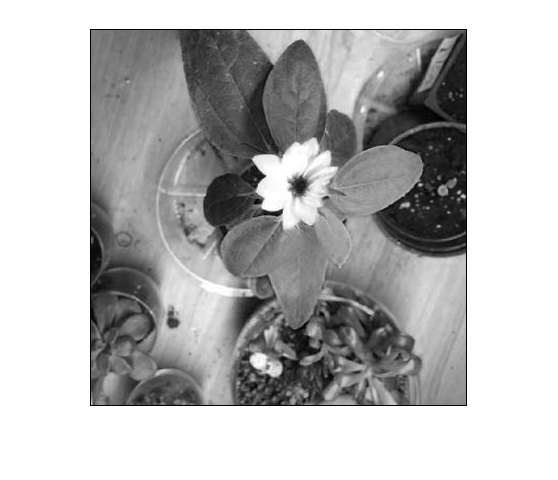

imshow(identityConv, []);

## Task 5

As expected, the image `identityConv` is the same as `redIm`. Using different kernels will have a different effect on your image. You can use the following kernel to blur an image.


$$\frac{1}{9}*\left\lbrack \begin{array}{ccc}
1 & 1 & 1\\
1 & 1 & 1\\
1 & 1 & 1
\end{array}\right\rbrack$$


At every pixel, this kernel will return an average of the pixel and its immediate neighbors.

blurK = 1/9 * [1 1 1; 1 1 1; 1 1 1]

blurK =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


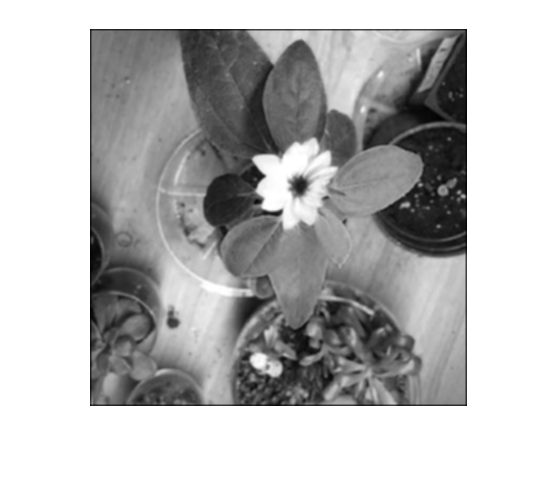

blurConv = conv2(blurK, redIm);
imshow(blurConv, []);

## Task 6

Edges are often found as features in early layers of a CNN. You can peform simple edge detection with the kernel


$$\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
1 & -4 & 1\\
0 & 1 & 0
\end{array}\right\rbrack$$


edgeK = [0 1 0; 1 -4 1; 0 1 0]

edgeK =      0     1     0
     1    -4     1
     0     1     0


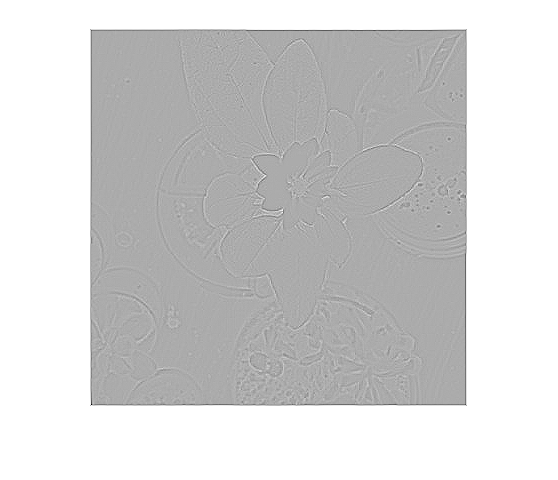

edgeConv = conv2(edgeK, redIm);
imshow(edgeConv, []);